# Detection of Osteoarthritis using Transfer Learning Technique

In this project we have created 2 different AI models, namely:

- **KL Grade model**: This detects the [KL Grade](https://radiopaedia.org/articles/kellgren-and-lawrence-system-for-classification-of-osteoarthritis) of the knee osteoarthirites in a person.

- **Ostearthirities detection model**: It just detects if the person has osteoarthirites or not since it can happen in any body joint(s) like neck, shoulder, femur bone, etc.

This project has been created and executed in [MATLAB R2024a](https://in.mathworks.com/products/new_products/release2024a.html)

## KL Grade model

This detects the [KL Grade](https://radiopaedia.org/articles/kellgren-and-lawrence-system-for-classification-of-osteoarthritis) of the knee osteoarthirites in a person. Here the the images have already preprocessed, thus no further preprocessing of images is required.

The images for this model were taken from the following dataset:

- [https://universe.roboflow.com/tru-projects-cqcql/knee-osteoarthritis-dataset/dataset/1](https://universe.roboflow.com/tru-projects-cqcql/knee-osteoarthritis-dataset/dataset/1)

- [https://www.kaggle.com/datasets/shashwatwork/knee-osteoarthritis-dataset-with-severity](https://www.kaggle.com/datasets/shashwatwork/knee-osteoarthritis-dataset-with-severity)

After downloading the dataset images, then it segerrated into the grade wise folders like "0" "1", etc. After this following operation were performed to create this model in Matlab

Create Datastore for the medical images.

imdsKLGrade = imageDatastore("sorted\KLGrade\","IncludeSubfolders",true,"LabelSource","foldernames");

Split the data into training, validation and test data

[imdsTrainKLGrade, imdsValKLGrade, imdsTestKLGrade] = splitEachLabel(imdsKLGrade, 0.7, 0.1, 'randomized');

View the top image of the default datastore

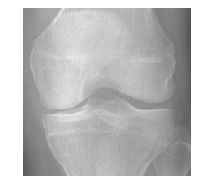

imshow(preview(imdsTrainKLGrade));

Shuffle the training dataset

imdsTrainKLGrade = shuffle(imdsTrainKLGrade);

Now we will do the transfer learning with the [densenet201 mode](https://www.kaggle.com/datasets/pytorch/densenet201)l. In order to do that the system must have this support package [Deep Learning Toolbox Model for DenseNet-201 Network](https://in.mathworks.com/matlabcentral/fileexchange/68803-deep-learning-toolbox-model-for-densenet-201-network). Dense Net 201 is trained on 1000 different classes, here we will delete its last layer and and change the output classes value from 1000 to 5 since we have 5 different classes to be identified (0, 1, 2, 3,4).

classNames = categories(imdsKLGrade.Labels);
numClasses = numel(classNames);
net = imagePretrainedNetwork("googlenet",NumClasses=numClasses);
inputSize = networkInputSize(net);

'networkInputSize' is used in Retrain Neural Network to Classify New Images.

[layerName,learnableNames] = networkHead(net);
net = freezeNetwork(net,LayerNamesToIgnore=layerName);

Now we have to augment the images so that when the images goes into training it made sure that no channels, size and other parameters remains same as required by the model.

pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( RandXReflection=true, RandXTranslation=pixelRange, RandYTranslation=pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrainKLGrade, DataAugmentation=imageAugmenter, ColorPreprocessing="gray2rgb");
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValKLGrade, ColorPreprocessing="gray2rgb");
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTestKLGrade, ColorPreprocessing="gray2rgb");

options = trainingOptions("adam", ValidationData=augimdsValidation, ValidationFrequency=5, Plots="training-progress", Metrics="accuracy", Verbose=false,Shuffle="every-epoch",ExecutionEnvironment="cpu");

Now we have train the newly created network from densenet201 model, so that the transfer learning could happen

net = trainnet(augimdsTrain,net,"crossentropy",options);
KlGradeModel = net;

Accuracy and Loss chart of the training

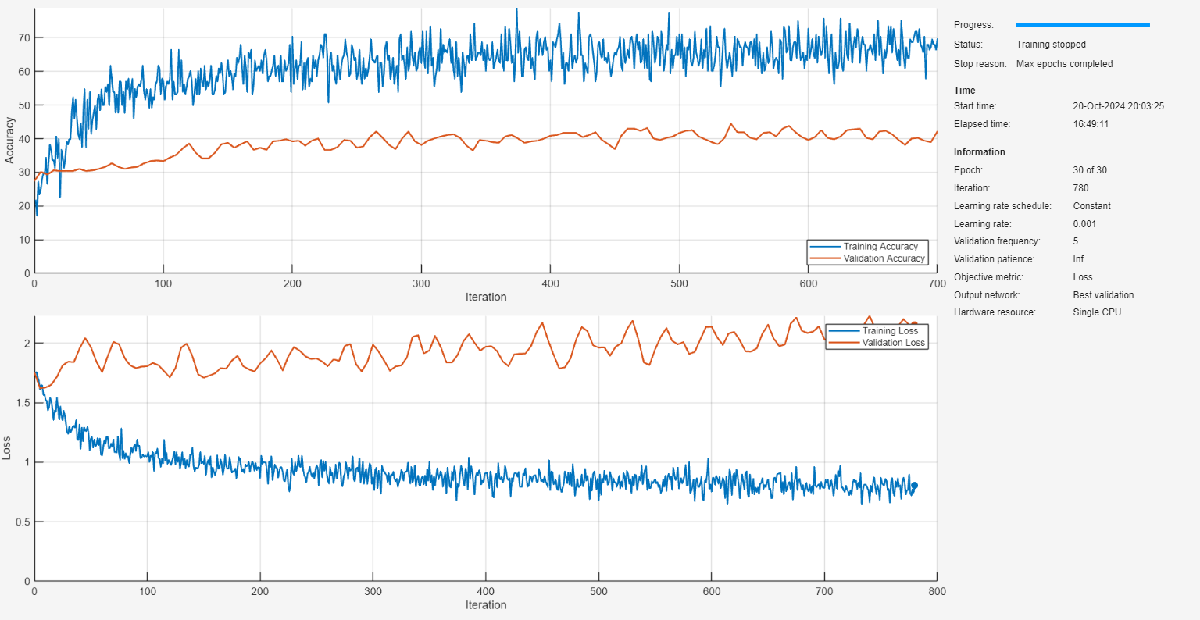

Accuracy and Loss chart of the training with Y axis on log scale

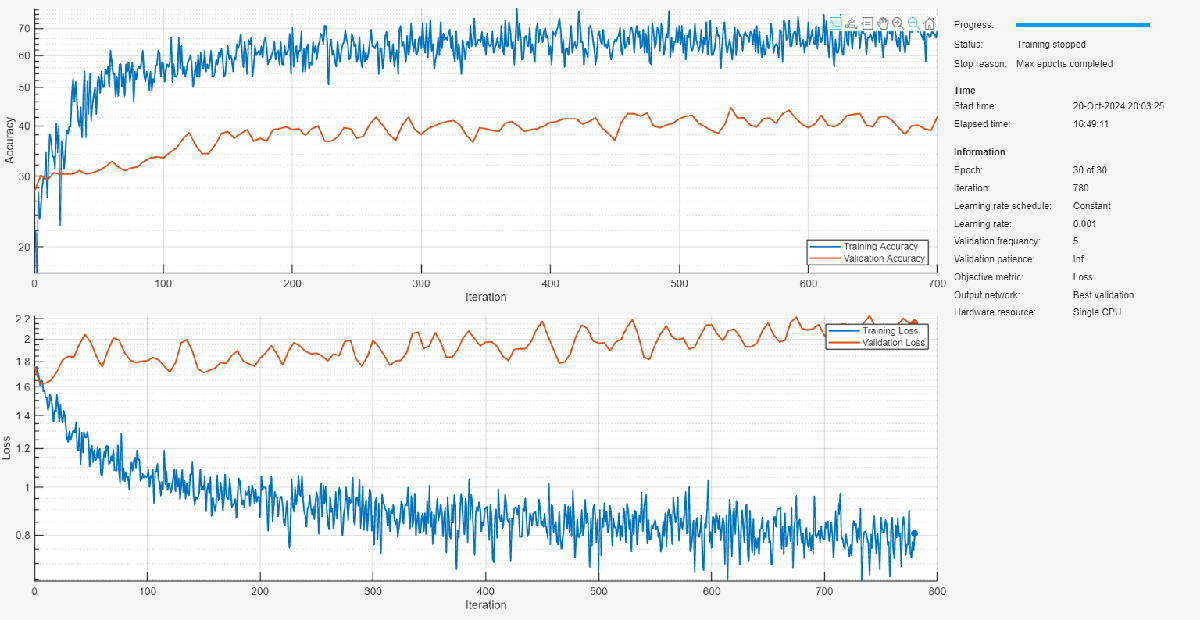

Now we have to test our newly trained network model

YTest = minibatchpredict(net,augimdsTest);
classNames = categories(imdsTestKLGrade.Labels);
YTestFinal = scores2label(YTest,classNames);

Now lets plot the confusion matrix

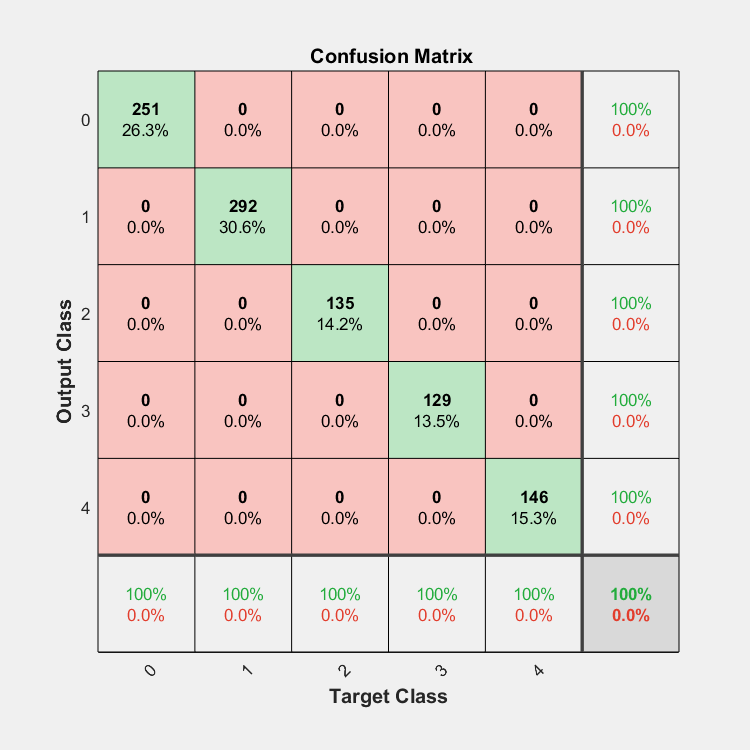

plotconfusion(YTestFinal,YTestFinal);

Now to plot other statistics of main interest we would be using this [package](https://in.mathworks.com/matlabcentral/fileexchange/86158-precision-specificity-sensitivity-accuracy-f1-score)

[C, ~] = confusionmat(imdsTestKLGrade.Labels, YTestFinal);
statsOfMeasure(C, 1);

stats = 9×4 table
          name                                classes                          macroAVG    microAVG
    ________________    ___________________________________________________    ________    ________

    "true_positive"         172        151         46         74         96      107.8       107.8 
    "false_positive"         79        141         89         55         50       82.8        82.8 
    "false_negative"         91        102        107         74         40       82.8        82.8 
    "true_negative"         611        559        711        750        767      679.6       679.6 
    "precision"         0.68526    0.51712    0.34074    0.57364    0.65753    0.55486     0.56558 
    "sensitivity"       0.65399    0.59684    0.30065        0.5    0.70588    0.55147     0.56558 
    "specificity"       0.88551    0.79857   

This model will be rebuilt for the final round

Now exporting to tensorflow and onyxnetwork

exportNetworkToTensorFlow(net,"googlenet");

exportONNXNetwork(net,"googlenetONNX.onnx");